## 找到变量之间的关系：回归方法

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

研究一组自变量(解释变量)和一个因变量(反应变量)的统计方法。

统计和机器学习工具箱提供了大量的回归算法(线性回归，非线性回归，广义线性模型)

有时候变量之间有很强的线性关系，有必要找一个近似这一趋势的模型，在拟合模型之前，计算相关性是识别变量是否具有这种简易关系的依据。

以散点图形式将数据点画在笛卡尔坐标系中，两个变量联系越强，数据点会有可能向一个特定方向分布。

协方差量化了两个变量之间线性关系的强度，而相关性通过无量纲的量来衡量线性关系的程度。


$$y=\alpha *x+\beta \;$$


x为解释变量，y为反应变量，α表示斜率，β表示在y轴上的截距

函数polyfit(),polyval()利用数据拟合一个线性关系。

一、最小二乘回归

数据集为注册的车辆数，不同地区的人口数，找一条回归线，逼近车辆注册数和人口之间存在某种关系。


$$y=\alpha *x+\beta \;$$


通过一系列观测结果$\left(x_1 ,y_1 \right),\cdots ,\left(x_n ,y_n \right)$,对于每一组观测结果，都能得到上面形式的等式，用矩阵形式表示为：


$$\left\lbrack \begin{array}{c}
y_1 \\
\vdots \;\\
y_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
x_1  & 1\\
\vdots \; & \vdots \;\\
x_n  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \;\\
\beta \;
\end{array}\right\rbrack$$


写成


$$Y=X\bullet A$$


用mldivide()求解方程组，也可以写成A=X\Y

%Least-squares regression
VehicleData = readtable('VehiclesItaly.xlsx');
summary(VehicleData)


Variables:

    Region: 20×1 cell array of character vectors

    Registrations: 20×1 double

        Values:

            Min            145263    
            Median        1117087    
            Max           5923476    

    Population: 20×1 double

        Values:

            Min           127329  
            Median     1814329.5  
            Max         10008349  



y=VehicleData.Registrations;
x=VehicleData.Population;
alpha=x\y

alpha =    0.606107192390367


VehicleRegFit=alpha*x;
scatter(x,y)
hold on
plot(x,VehicleRegFit)

即$y=0\ldotp 6061x,\beta =0$

结果显示：每个区域的人口数量和车辆注册数有一个正的相关性。

"\"运算执行了一次最小二乘回归，原理是参数估计通过寻找能最小化反应变量的观测值和拟合值的偏差的平方和来实现。

即 希望最小化以下损失函数


$$E=\sum_{i=1}^n {\left(\alpha \;x_i +\beta -y_i \right)}^2$$


目的是使得实际样本点$\left(x_i ,y_i \right)$和对应的回归直线上估计样本点之间距离的平方和最小。两点距离$r_i =y_i -\left(\alpha \;x_i +\beta \;\right)$称为残差。

Residual=y-VehicleRegFit;
stem(Residual) %残差茎叶图

以x轴为基准线，把数据序列作茎叶画出来。

残差衡量了回归线和相应数据点拟合的好坏程度，如果残差序列表现为一种随机分布，说明模型拟合得很好。

决定系数R的平方也可衡量模型的效果，$R^2$介于0~1之间，越大越好。

$R^2$反应响应变量的变异中有多少百分比可由解释变量来解释。

残差平方和RSS：


$${\textrm{SS}}_{\textrm{res}} =\sum_{i=1}^n {\left(y_i -\alpha \;x_i -\beta \right)}^2$$


总平方和SST：


$${\textrm{SS}}_{\textrm{tot}} =\sum_{i=1}^n {\left(y_i -\;y_{\textrm{mean}} \right)}^2$$



$$R^2 =1-\frac{{\textrm{SS}}_{\textrm{res}} }{{\textrm{SS}}_{\textrm{tot}} }=1-\frac{\sum_{i=1}^n {\left(y_i -\alpha \;x_i -\beta \right)}^2 }{\sum_{i=1}^n {\left(y_i -\;y_{\textrm{mean}} \right)}^2 }$$
 

Rsq1 = 1 - sum((y - VehicleRegFit).^2)/sum((y - mean(y)).^2)

Rsq1 =    0.993461688600303


越接近于1，说明拟合的回归线和简单的平均线相比，拟合的越好。

下面引入截距参数，提升模拟的精度

X = [ones(length(x),1) x];
alpha_beta = X\y

alpha_beta = 	1.0e+04 *

   7.054852869816421
   0.000059211616533


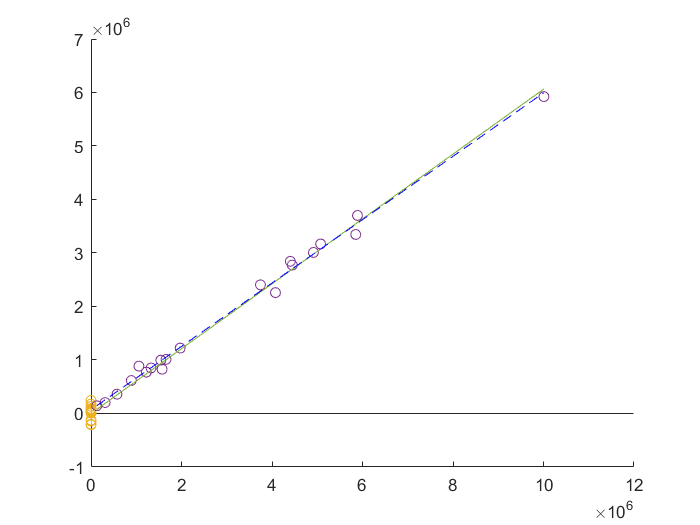

VehicleRegFit2 = X* alpha_beta;
scatter(x,y)
hold on
plot(x,VehicleRegFit)
plot(x,VehicleRegFit2,'--b')

计算决定系数，比较两个模型的表现：

Rsq2 = 1 - sum((y - VehicleRegFit2).^2)/sum((y - mean(y)).^2)

Rsq2 =    0.994384612656348


明显第二个带截距的模型拟合的更好。

二、基本拟合接口

图形化方式

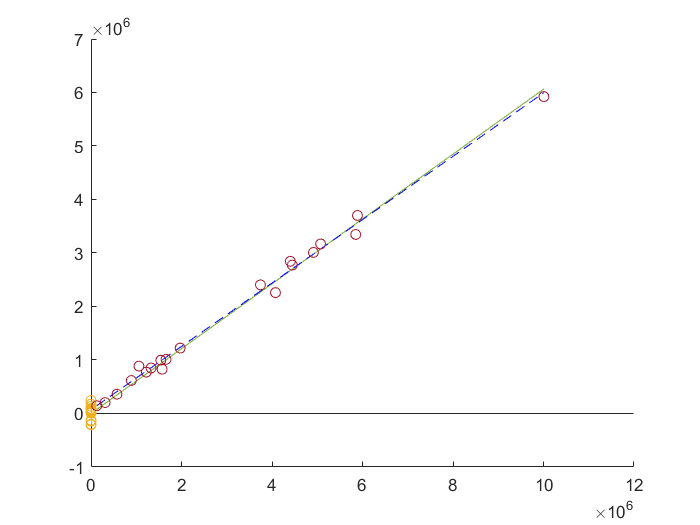

%Basic Fitting interface
VehicleData = readtable('VehiclesItaly.xlsx');
scatter(VehicleData.Population,VehicleData.Registrations)

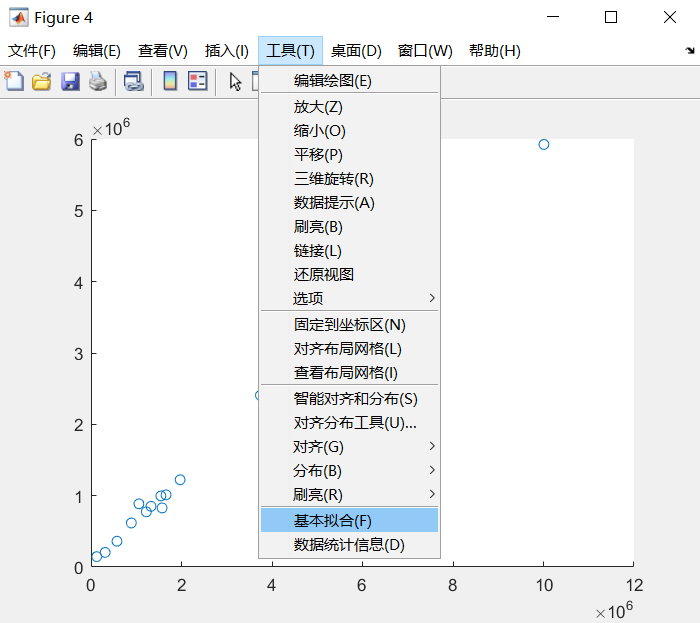

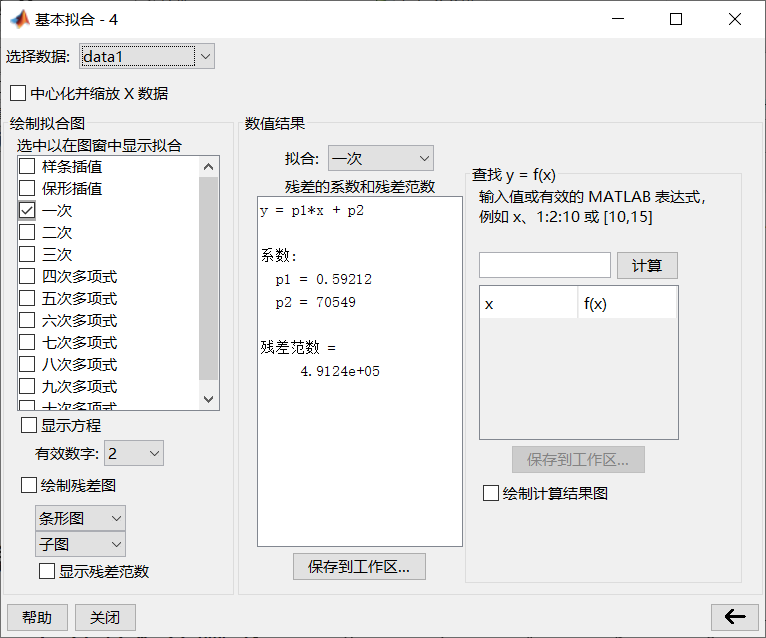

展开有三个面板。

- 选择模型及绘图选项

- 检查并导出模型系数及残差范数

- 检查并导出内插值及外插值

第三个面板中，可以用新的数据点计算模型的估计值。

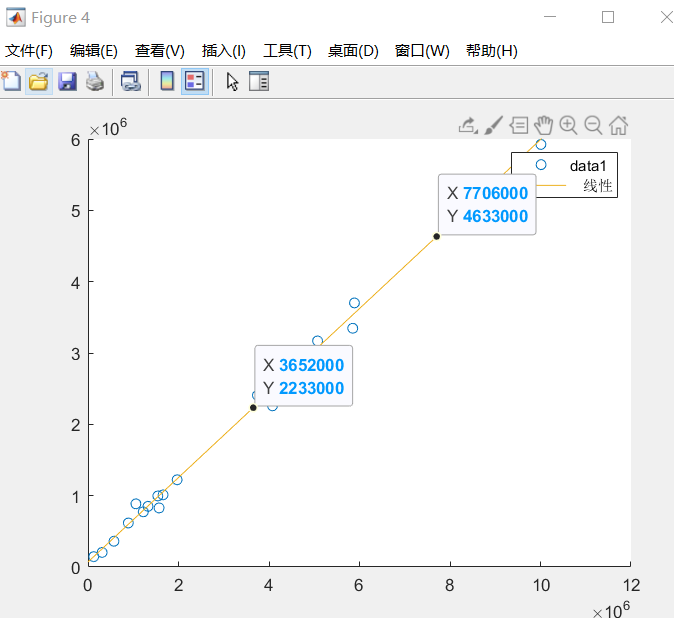

散点图和对应的回归直线结果。

### 三、如何创建一个线性回归模型

使用fitlm()函数，创建一个LinearModel对象，有一系列属性，可通过鼠标点击方式查看。

包含plot，plotResiduals，plotDiagnostics等方法。可以用来创建图像和检查模型。

LinearModel对象包括训练数据，模型描述，模型诊断信息和拟合好的参数。

fitlm()函数默认选择表或数据集中最后一个变量作响应变量，可自行指定响应变量和解释变量，还可以用ResponseVar名称-值参数来指定一个特定的列作为响应变量，用Predictor Vars名-值参数作为解释变量的列。

解释变量可以是数值型，也可以是任意的分组变量类型。

公式'Y~A+B+C'，响应变量背后总是跟着符号~，公式默认有一个截距项，为消除截距项，在公式中使用-1.

%linear regression model
VehicleData = readtable('VehiclesItaly.xlsx');
VehicleData(1:10,:)

ans = 10×3 table
             Region              Registrations    Population
    _________________________    _____________    __________

    {'Valle d'Aosta'        }        145263         127329  
    {'Molise'               }        204477         312027  
    {'Basilicata'           }        361034         573694  
    {'Umbria'               }        616716         891181  
    {'Trentino Alto Adige'  }        885665        1059114  
    {'Friuli Venezia Giulia'}        773600        1221218  
    {'Abruzzo'              }        850513        1326513  
    {'Marche'               }        996733        1543752  
    {'Liguria'              }        827967        1571053  
    {'Sardegna'             }       1011436        1658138  


lrm = fitlm(VehicleData,'Registrations~Population')

lrm = 线性回归模型:
    Registrations ~ 1 + Population

估计系数:
                       Estimate               SE                tStat                 pValue       
                   ________________    ________________    ________________    ____________________

    (Intercept)    70548.5286981644    41016.4986900493    1.72000368025756       0.102578204166719
    Population      0.5921161653347    0.01048777416626    56.4577531846159    1.03226869302289e-21


观测值数目: 20，误差自由度: 18
均方根误差: 1.16e+05
R 方: 0.994，调整 R 方 0.994
F 统计量(常量模型): 3.19e+03，p 值 = 1.03e-21

拟合出一个线性回归模型，以Registrations为响应变量，以Population为解释变量。

结论：

Estimate：参数的估计值

SE：估计值的标准误差

Tstat：对每个参数逐一进行t检验法，零假设为参数值为0，即检验：自变量对因变量是否有显著的关系。

pValue：对所有自变量的系数同时进行F检验，计算出F统计量对应的p值，p值小于0.05(α=0.05)

拒绝原假设，回归效果显著。

F检验：回归方程的显著性检验，回归的总体效果，因变量和自变量的线性组合之间是否有显著的线性关系。

Error degrees of  freedom：样本数减去估计的参数数，20-2=18，有两个解释变量

RMSE：均方误差的平方根

统计检验的结果没有一个绝对值，不具有确定性，是一个概率，因此接受或拒绝可能对也可能错，通过检验的显著性水平来衡量犯错的概率。

p值量化了样本和总体假设之间的差异完全是机会差异造成的这一可能性。本例中的p值远低于显著性水平α=0.05，因此被观测到的差异是统计显著的。

利用残差去除异常值

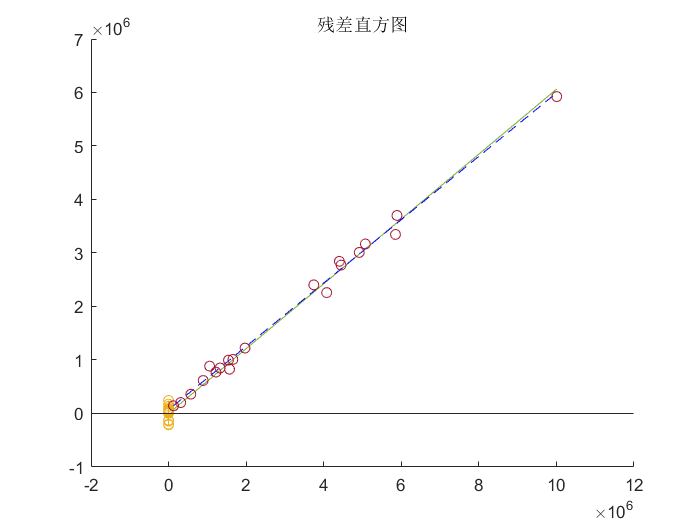

plotResiduals(lrm) %残差柱状图

分布在负值区域不对称，低于-2*10^5的残差值有可能是一个异常值出现的地方。

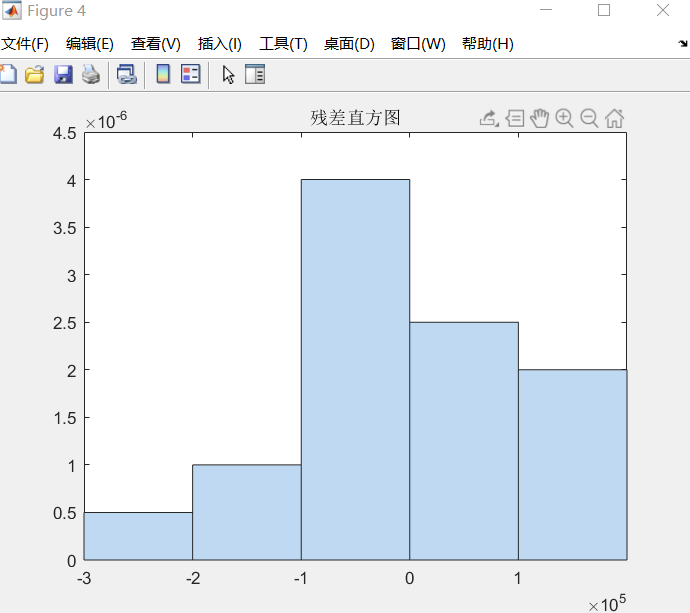

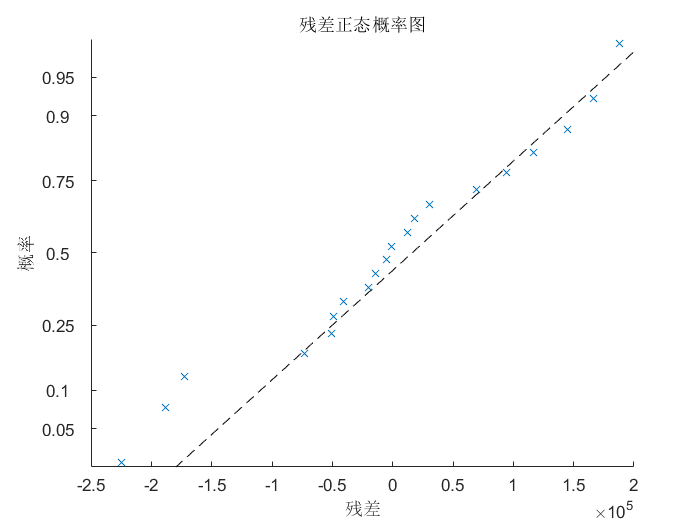

plotResiduals(lrm,'probability')

残差概率图，于对应的标准正态分布比较

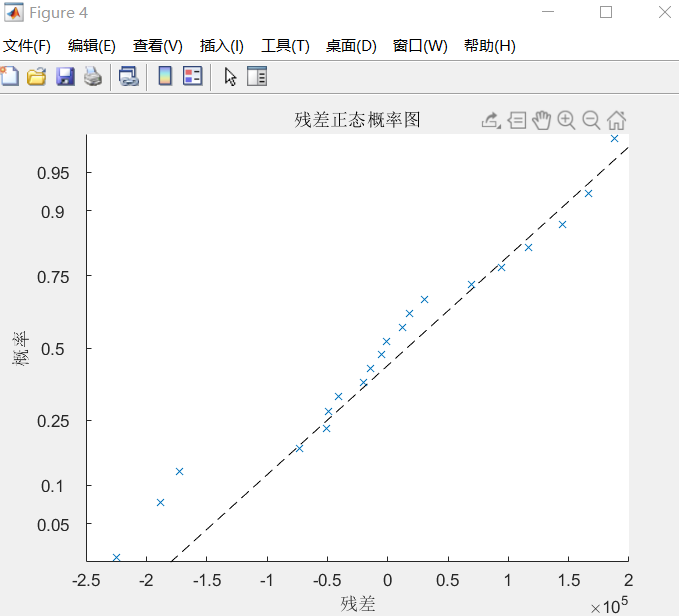

左下角有3个偏离虚线很远，移除

outliers = find(lrm.Residuals.Raw < -1.5*10^5)

outliers =      9
    13
    18


lrm2 = fitlm(VehicleData,'Registrations~Population','Exclude',outliers)

lrm2 = 线性回归模型:
    Registrations ~ 1 + Population

估计系数:
                       Estimate                 SE                  tStat                 pValue       
                   _________________    ___________________    ________________    ____________________

    (Intercept)     89425.7478733022       30264.4135079314    2.95481516104273     0.00983668170948984
    Population     0.597505294077251    0.00785163316894466     76.099491815352    7.91934719667414e-21


观测值数目: 17，误差自由度: 15
均方根误差: 8.25e+04
R 方: 0.997，调整 R 方 0.997
F 统计量(常量模型): 5.79e+03，p 值 = 7.92e-21

$R^2 \;$从0.994提升到0.997，可见图中全体残差值分布比较接近于正态分布。

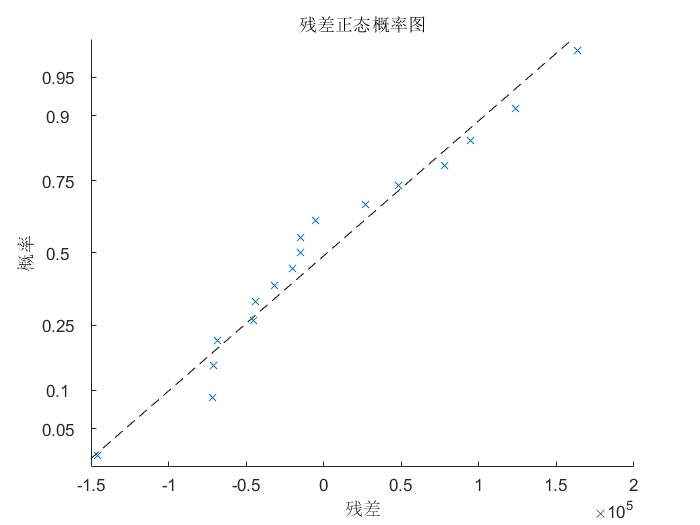

plotResiduals(lrm2,'probability')

为降低异常值造成的影响，也可以使用稳健的最小二乘回归法

lrm1 = fitlm(VehicleData,'Registrations~Population')

lrm1 = 线性回归模型:
    Registrations ~ 1 + Population

估计系数:
                       Estimate               SE                tStat                 pValue       
                   ________________    ________________    ________________    ____________________

    (Intercept)    70548.5286981644    41016.4986900493    1.72000368025756       0.102578204166719
    Population      0.5921161653347    0.01048777416626    56.4577531846159    1.03226869302289e-21


观测值数目: 20，误差自由度: 18
均方根误差: 1.16e+05
R 方: 0.994，调整 R 方 0.994
F 统计量(常量模型): 3.19e+03，p 值 = 1.03e-21

lrm2 = fitlm(VehicleData,'Registrations~Population','RobustOpts','on')

lrm2 = 线性回归模型(稳健拟合):
    Registrations ~ 1 + Population

估计系数:
                       Estimate                 SE                   tStat                 pValue       
                   _________________    ___________________    _________________    ____________________

    (Intercept)     25058.9987179127        27076.447128572    0.925490652407993       0.366953354017731
    Population     0.621690745783601    0.00692335210899012      89.796205074753    2.50497840785037e-25


观测值数目: 20，误差自由度: 18
均方根误差: 7.64e+04
R 方: 0.998，调整 R 方 0.998
F 统计量(常量模型): 8.07e+03，p 值 = 2.49e-25

$R^2 \;$从0.994提升到0.998，pValue从1.03e^-2降低到2.49e^-25

subplot(1,2,1)
plotResiduals(lrm1,'probability')
subplot(1,2,2)
plotResiduals(lrm2,'probability')

轻松移除异常值(5个点)

outliers = find((lrm2.Residuals.Raw < -1.5*10^5) | (lrm2.Residuals.Raw > 1.5*10^5))

outliers =      5
     9
    13
    18
    20


lrm3 = fitlm(VehicleData,'Registrations~Population','RobustOpts','on','Exclude',outliers)

lrm3 = 线性回归模型(稳健拟合):
    Registrations ~ 1 + Population

估计系数:
                       Estimate                 SE                  tStat                 pValue       
                   _________________    ___________________    ________________    ____________________

    (Intercept)     25243.6787781565       19164.0443550886    1.31724172154995       0.210503510195041
    Population     0.621842786091488    0.00603435042773327    103.050492930202    2.53736054720878e-20


观测值数目: 15，误差自由度: 13
均方根误差: 4.46e+04
R 方: 0.999，调整 R 方 0.999
F 统计量(常量模型): 1.06e+04，p 值 = 2.54e-20

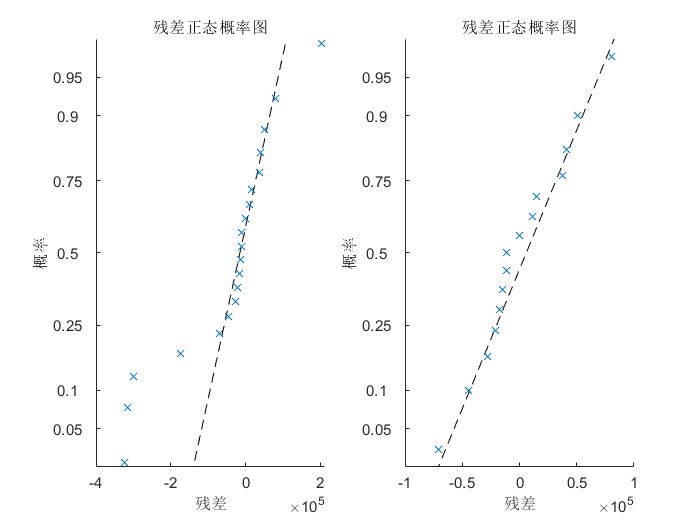

subplot(1,2,1)
plotResiduals(lrm2,'probability')
subplot(1,2,2)
plotResiduals(lrm3,'probability')

稳健回归方法首先会给每个数据点赋予一个权重，然后进行自动迭代的加权。

## 多元线性回归


$$y=\beta_0 +\beta {\;}_1 x_1 +\cdots +\beta {\;}_n x_n$$


其中，n个解释变量，y为响应变量，$\beta {\;}_i$衡量了当其他变量不变时，单位$x_i$的变化导致y的变化量，多元线性回归力图找到最能表达数据集的一个高维平面。

优化目标：


$$\sum_i {\left\lbrack y_i -\left(\beta {\;}_0 +\beta {\;}_1 x_{1,i} +\beta {\;}_2 x_{2,i} +\cdots +\beta {\;}_n x_{n,i} \right)\right\rbrack }^2$$



$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \;\\
y_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_{1,1}  & x_{1,2}  & \cdots \; & x_{1,n} \\
1 & x_{2,1}  & x_{2,2}  & \cdots  & x_{2,n} \\
\cdots  & \cdots  & \cdots  & \cdots  & \cdots \\
1 & x_{n,1}  & x_{n,2}  & \cdots  & x_{n,n} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_0 \\
\beta_1 \\
\cdots \\
\beta_n 
\end{array}\right\rbrack$$


简记为


$$Y=X*A$$


matlab执行：$A=X\backslash Y$

案例，将hald.mat文件导入matlab工作间，不同水泥混合物反应热的观测结果。

%Multiple Linear Regression
load hald
whos

  Name                               Size             Bytes  Class                                        Attributes

  A                                  5x1                 40  double                                                 
  AirfoilSelfNoise                1503x6              74380  table                                                  
  Cor                                3x3                 72  double                                                 
  Cov                                4x4                128  double                                                 
  CovMatA                            4x4                128  double                                                 
  Description                       22x58              2552  char                                                   
  EmergencyCalls                    24x4                768  double                                                 
  EmployeesSalary                  120x3               4002  ta

变量中的4列分别对应以下4个成分3CaO.Al2O3，3CaO.SiO2...

所占的百分比：

heat变量：混合物的反应热。

X = [ones(13,1), ingredients];
Y=(heat);
A=X\Y

A =   62.405369299917552
   1.551102647508450
   0.510167579684917
   0.101909403579665
  -0.144061029071012


lm=fitlm(ingredients,Y)

lm = 线性回归模型:
    y ~ 1 + x1 + x2 + x3 + x4

估计系数:
                        Estimate                SE                  tStat                 pValue      
                   __________________    _________________    __________________    __________________

    (Intercept)      62.4053692999174      70.070959208557     0.890602469336492     0.399133563385699
    x1               1.55110264750845    0.744769867131215      2.08266031691528    0.0708216874297928
    x2              0.510167579684918    0.723788001835394     0.704857746178752     0.500901103474407
    x3              0.101909403579667    0.754709045051535     0.135031379639432     0.895922690510132
    x4             -0.144061029071011    0.709052063446719    -0.203174120064931     0.844071473291937


观测值数目: 13，误差自由度: 8
均方根误差: 2.45
R 方: 0.982，调整 R 方 0.974
F 统计量(常量模型): 111，p 值 = 4.76e-07

b=regress(Y,X)

b =   62.405369299917439
   1.551102647508451
   0.510167579684918
   0.101909403579667
  -0.144061029071011


### 包含分类变量的多元线性回归

3类员工，经理，技术人员，一般员工

%MLR with Categorical Predictor 
EmployeesSalary = readtable('employees.xlsx');
summary(EmployeesSalary)


Variables:

    YearsExperience: 120×1 double

        Values:

            Min                1       
            Median          20.5       
            Max               40       

    Salary: 120×1 double

        Values:

            Min          20   
            Median       41   
            Max          82   

    LevelOfEmployee: 120×1 cell array of character vectors



将职工类别，元胞数组格式转换为分类数组的格式

EmployeesSalary.LevelOfEmployee=categorical(EmployeesSalary.LevelOfEmployee);
class(EmployeesSalary.LevelOfEmployee)

ans = 'categorical'

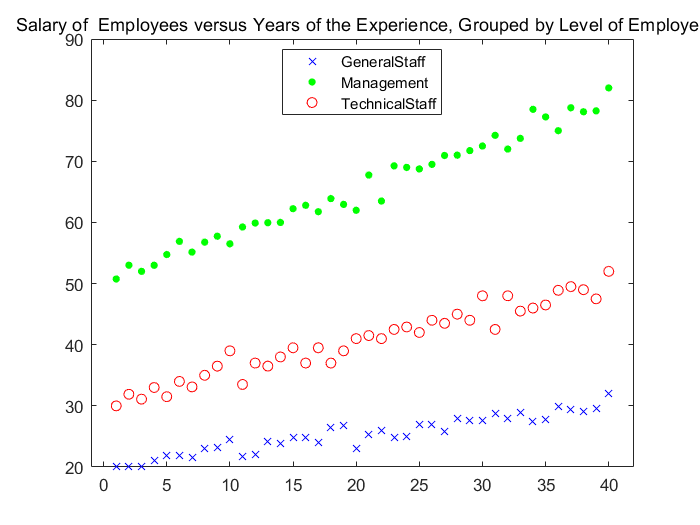

figure()
gscatter(EmployeesSalary.YearsExperience, EmployeesSalary. Salary, EmployeesSalary.LevelOfEmployee,'bgr','x.o')
title('Salary of  Employees versus Years of the Experience, Grouped by Level of Employee')

分三个不同职工的类别，为每个类别员工画出员工和员工工作年份的散点图。

fitlm() 工资与工作年限之间的关系，不同员工种类的工资有明显差别。

用salary作响应变量，用yearsExperience和LevelOfEmployee作解释变量，因为LevelOfEmployee是一个包含3类分类变量，在模型中以虚拟变量的形式存在(dummy  indicator variable).

回归方程中增加YearsExperience*LevelOfEmployee交叉项

LMcat = fitlm(EmployeesSalary,'Salary~YearsExperience*LevelOfEmployee')

LMcat = 线性回归模型:
    Salary ~ 1 + YearsExperience*LevelOfEmployee

估计系数:
                                                          Estimate                 SE                 tStat                 pValue       
                                                      _________________    __________________    ________________    ____________________

    (Intercept)                                        20.1985769230769     0.408840879802904    49.4044943177266    8.06243764688527e-79
    YearsExperience                                   0.250606003752345    0.0173778282873773    14.4210196814051    1.83584346302717e-27
    LevelOfEmployee_Management                         30.2472692307692     0.578188317069815    52.3138713422273     1.5567697677821e-81
    LevelOfEmployee_TechnicalStaff                     10.3687307692308     0.578188317069815    17.9331378084189    5.66002167895397e-35
    YearsExperience:LevelOfEmployee_Management        0.487560037523452    0.0245759604485997    19

一个虚拟变量可以取值0或1，n个种类的分类变量被表达为n-1个虚拟变量。

模型结果：

Salary=20.2+0.25*YearsExperience+30.2*LevelOfEmployee(Management)+10.4*LevelOfEmployee(TechnicalStaff)

+0.49*YearsExperience*LevelOfEmployee(Management)

+0.24*YearsExperience*LevelOfEmployee(TechnicalStaff)

仅靠一个等式来描述整个系统，不足以让我们对工资有一个完整的估计，分出3个模型，每个模型对应一个员工类别。

LevelOfEmployee(GeneeralStaff):

Salary=20.2+0.25*YearsExperience

LevelOfEmployee(TechnicalStaff):

Salary=(20.2+10.4)+(0.25+0.24)*YearsExperience

LevelOfEmployee(Management):

Salary=(20.2+30.2)+(0.25+0.49)*YearsExperience

为更好理解，将数据散点图和3条线画在一张图中：

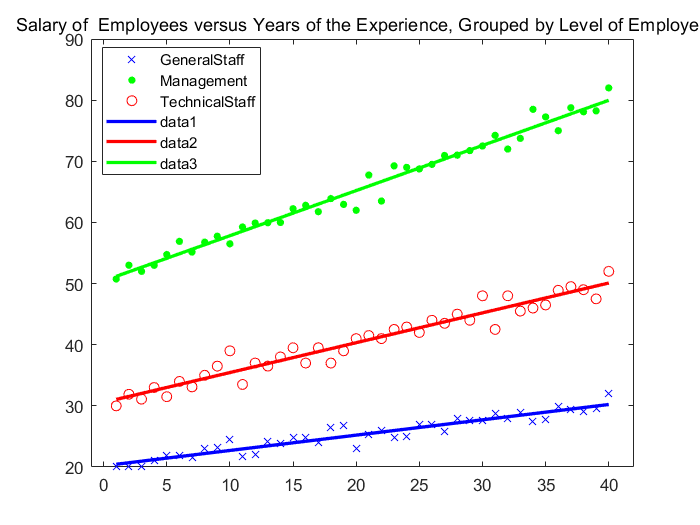

Xvalues = linspace(min(EmployeesSalary.YearsExperience),max(EmployeesSalary.YearsExperience));
figure()
gscatter(EmployeesSalary.YearsExperience, EmployeesSalary.Salary, EmployeesSalary.LevelOfEmployee,'bgr','x.o')
title('Salary of  Employees versus Years of the Experience, Grouped by Level of Employee')
line(Xvalues,feval(LMcat,Xvalues,'GeneralStaff'),'Color','b','LineWidth',2)
line(Xvalues,feval(LMcat,Xvalues,'TechnicalStaff'),'Color','r','LineWidth',2)
line(Xvalues,feval(LMcat,Xvalues,'Management'),'Color','g','LineWidth',2)

### 多项式回归

解释变量可以以二次或更高次的形式出现。

模型为


$$y=\beta_0 +\beta_1 x+\beta_2 x^2$$


多项式回归的模型图形是一条曲线，变量间的关系看上去是弯曲的，往往使用多项式回归。

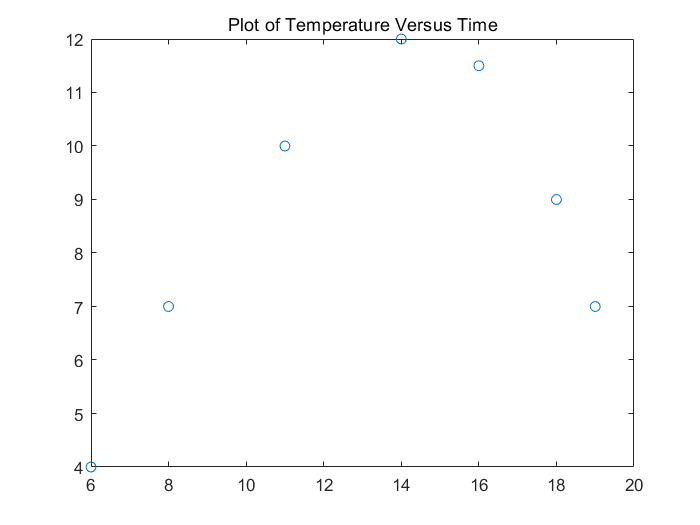

%Polynomial regression
Time = [6 8 11 14 16 18 19];
Temp = [4 7 10 12 11.5 9 7];
plot(Time,Temp,'o')
title('Plot of Temperature Versus Time')

上面的图形显示了一天之内几个时间点的温度。

可以试试用二次抛物线来建模。

coeff = polyfit(Time,Temp,2) %二阶拟合

coeff =   -0.140800430287352   3.820658801292613 -14.256232198385183



$$\textrm{Temp}=-0\ldotp 1408*{\textrm{time}}^2 +3\ldotp 8207*\textrm{time}-14\ldotp 2562$$


拟合完毕，画出模型曲线，并验证曲线是否能够符合数据趋势。创建新的时间点TimeNew，然后用函数polyval()获取这些点的对用函数值。将原始数据和拟合的模型画在同一张图上。

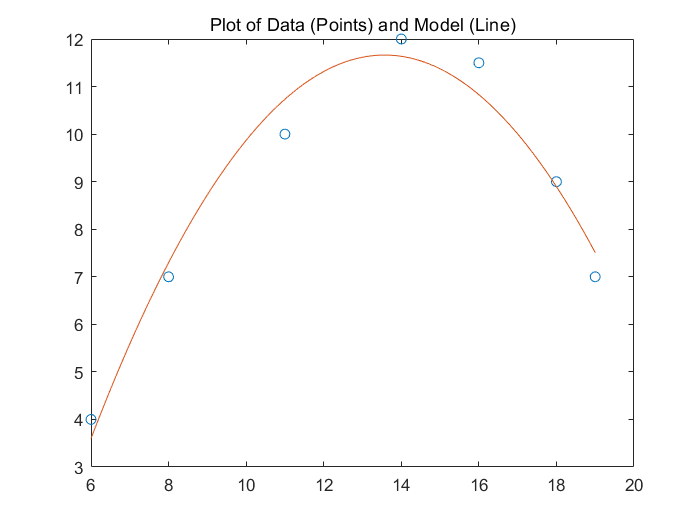

TimeNew = 6:0.1:19;
TempNew = polyval(coeff,TimeNew);
figure
plot(Time,Temp,'o', TimeNew, TempNew)
title('Plot of Data (Points) and Model (Line)')

多项式的阶数过高会导致模型不准确。

回归学习器App

图形界面，易于理解。

自动化地训练，寻找最好的回归模型种类（线性回归，回归树，支持向量机和决策树等）

可以把APP中的模型导出到工作区，生成matlab代码以重新创建训练好的模型，之后重用这个模型。

从加州大学尔湾分校机器学习数据集UCI Machine Learning Repository 中下载需要的数据集。

NASA数据集，消声风洞中对二维或三维的机翼桨叶剖面进行的空气动力学和声音测试。

包含频率，迎角，弦长(chlenM)，自由气流速度，进口侧排量厚度，声压级dB.

%Regression Learner App
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/00291/airfoil_self_noise.dat';
websave('AirfoilSelfNoise.csv',url);
varnames = {' FreqH '; 'AngleD'; 'ChLenM'; 'FStVelMs'; ' SucSDTM ';' SPLdB'}; 
AirfoilSelfNoise = readtable('AirfoilSelfNoise.csv');
AirfoilSelfNoise.Properties.VariableNames = varnames;


实际上这个数已经从网络下载好了，存储到本地，指定变量了名。

将数据导入到matlab工作区中，接着使用Regression Learning APP

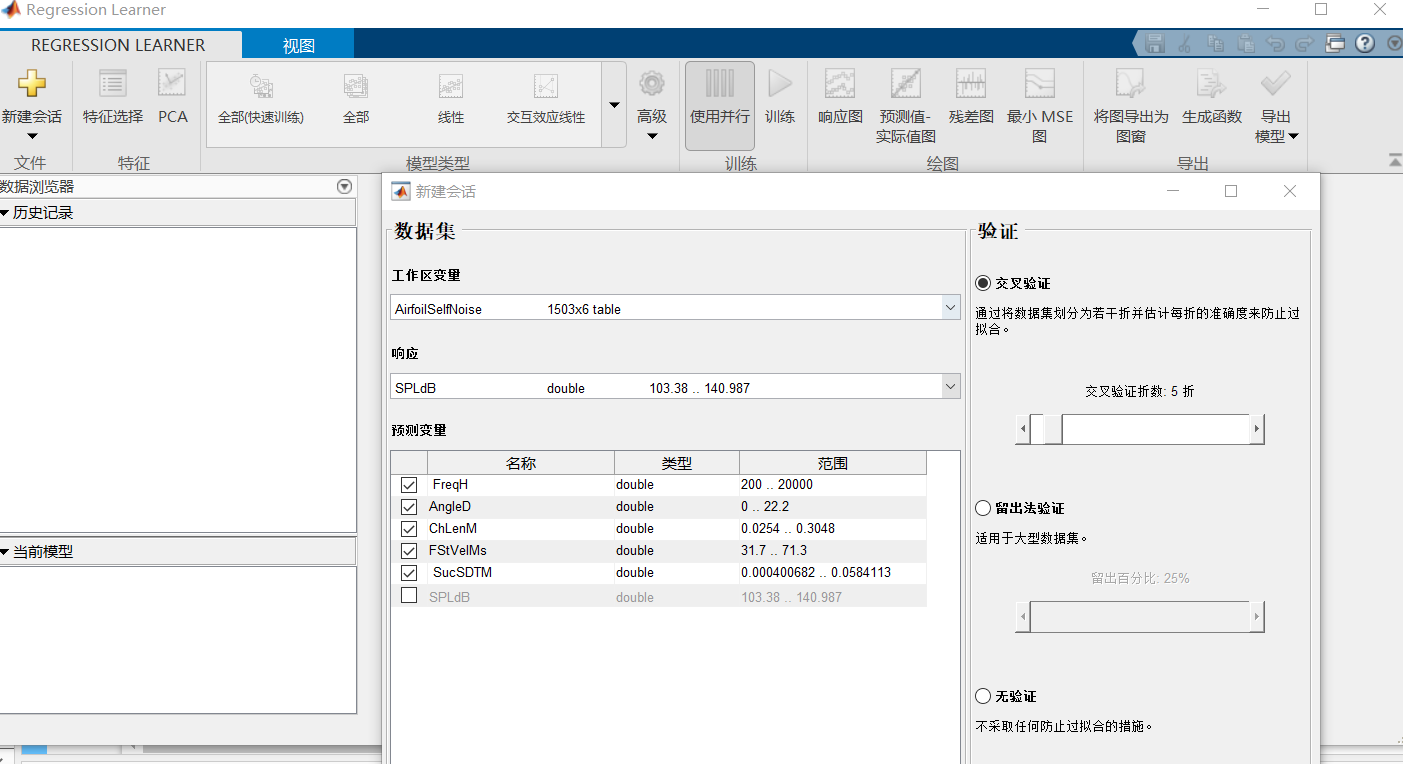

选择数据源，选择解释变量和响应变量，确定验证方法(检验拟合模型的预测精度)。

交叉验证方法使用滑动条来选择数据拆分的份数。二分法，选择原始数据中的一部分作为验证集。如果不选用验证方法选项，那么在训练中也就不会使用验证方法来过拟合了。

回归类型：

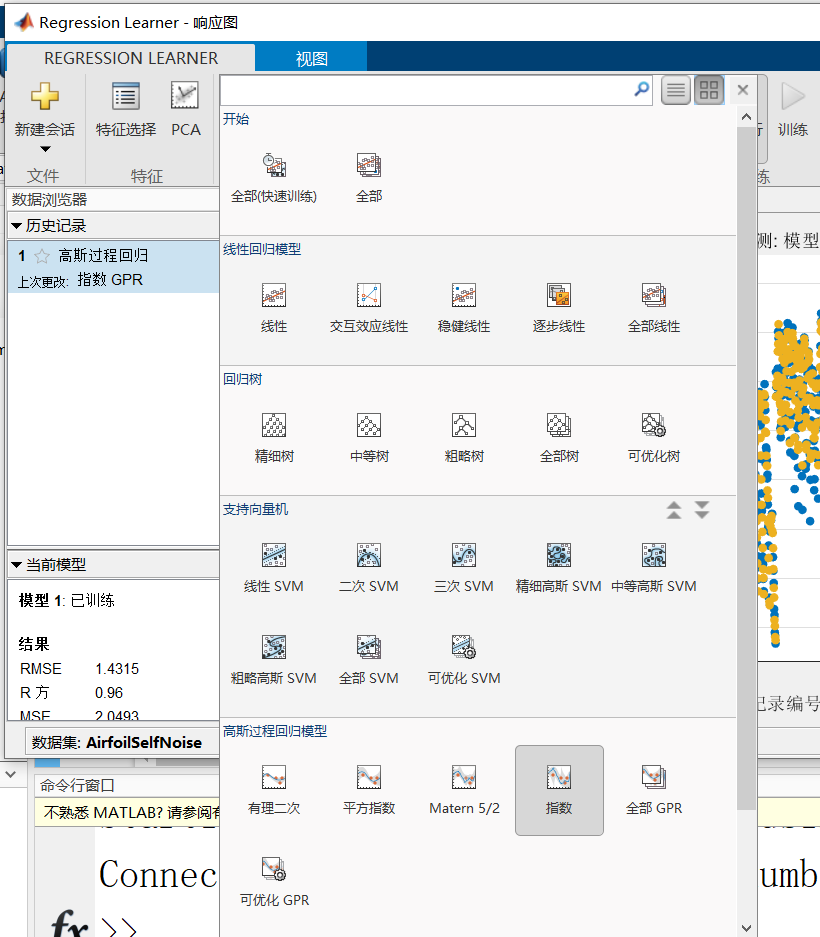

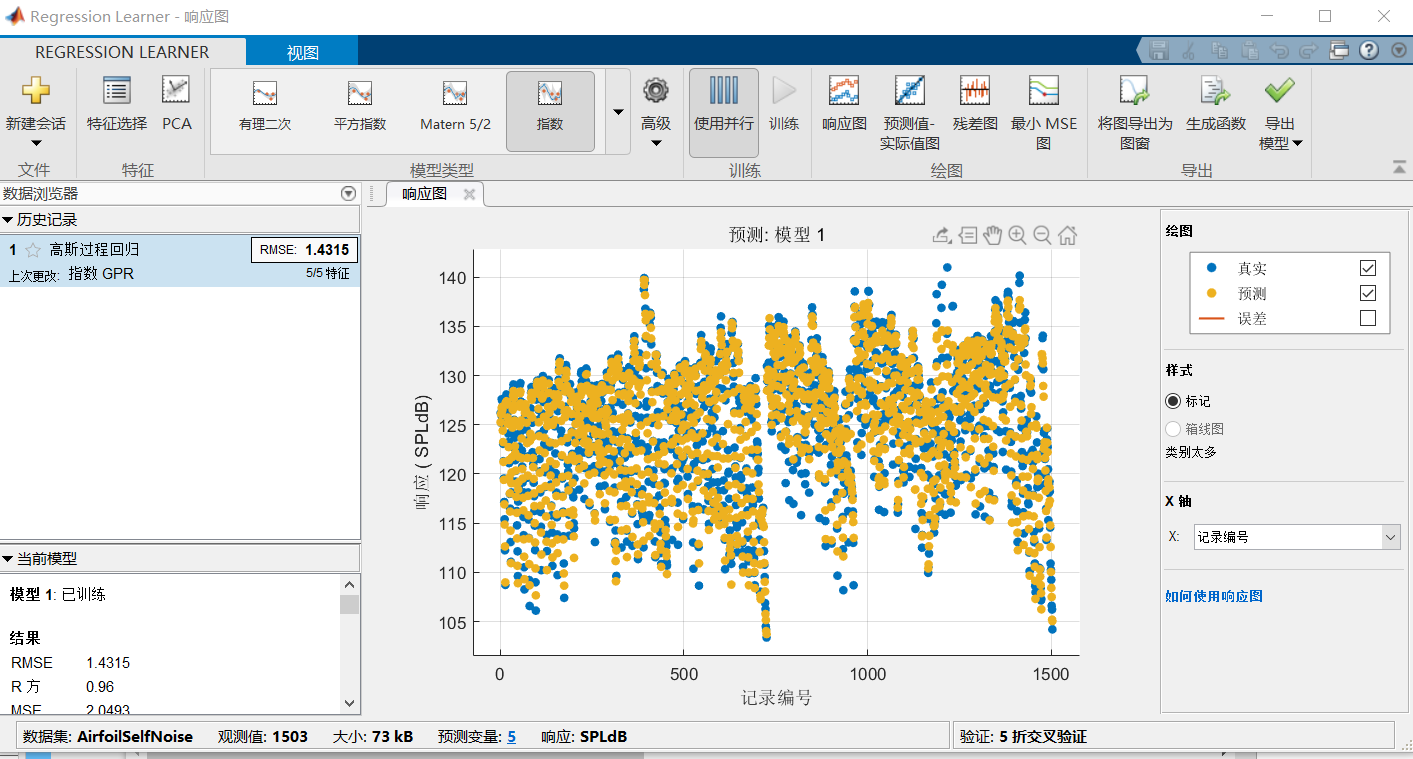

选择快速训练会先训练一部分收敛较快的模型：

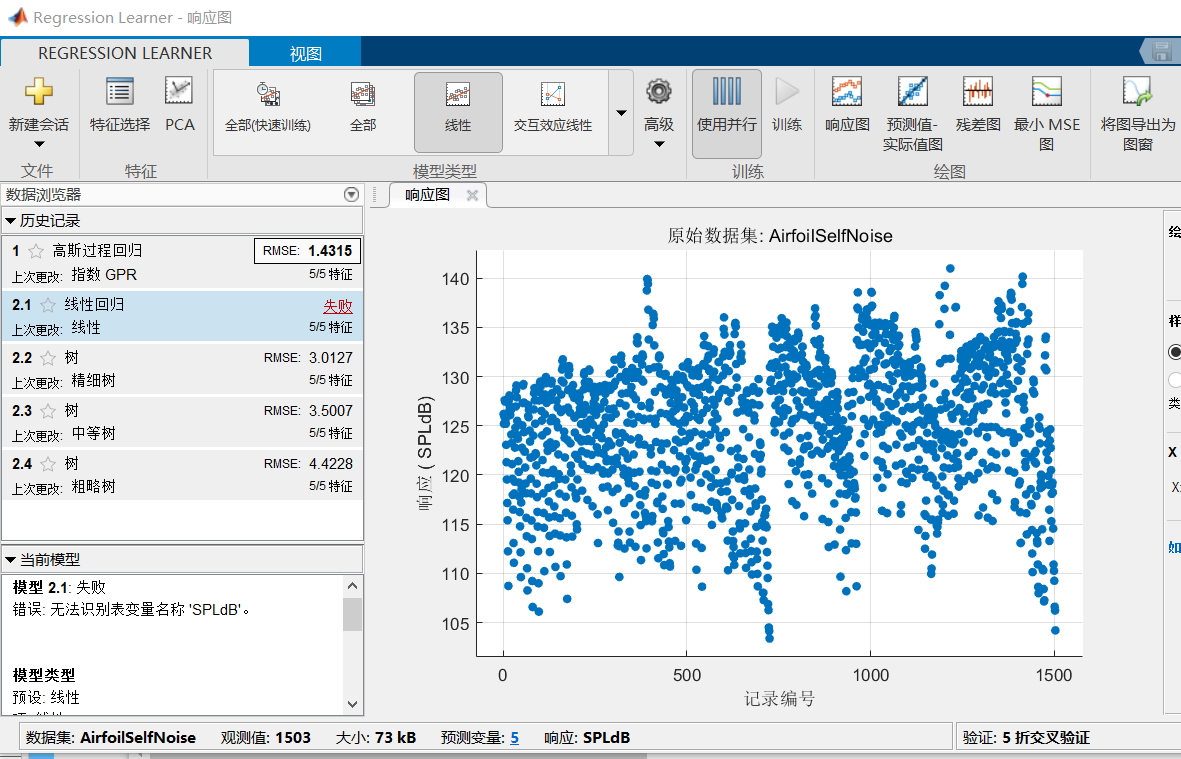

可以看到训练完成后，RMSE最小的为3.0127的树回归。

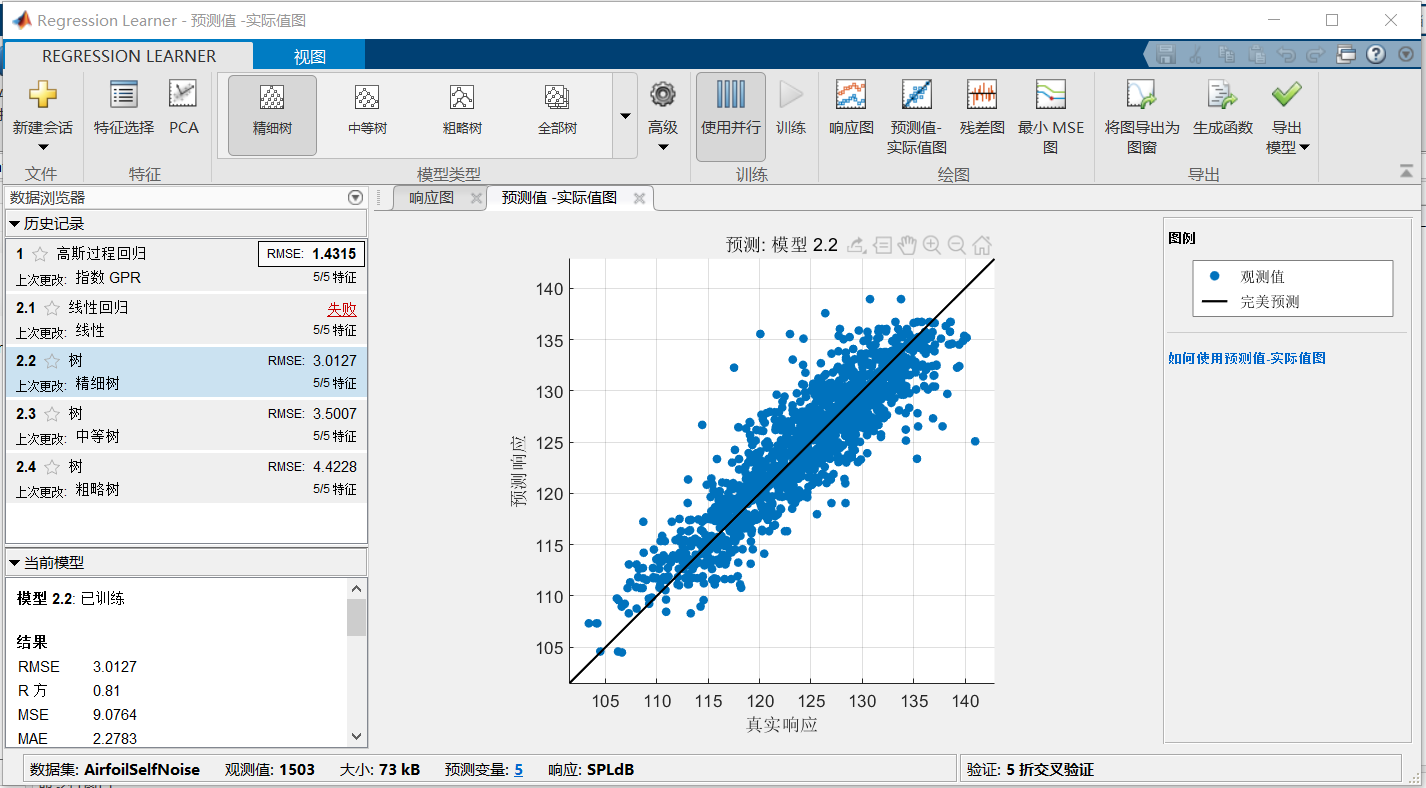

获得回归模型后，可以导出到工作区，以使用其预测新数据。选择history功能区中最好的模型，在界面上选择export导出模型，3个选项，Export Model：把用于训练的数据包含在导出的工作区结构体中，结构体包含一个回归模型对象。Export compact Model：不包含训练数据。

Generate  Matlab  code： 产生相应的代码，可以使用新数据继续训练模型。

参考文献

- [意]朱塞佩.恰布罗，张雅仁等译，人民邮电出版社，matlab机器学习，2020年5月